# TKEO Signal Denoising

## Teager-Kaiser Energy-Tracking Operator formula

- y(t) = x(t)^2 - x(t-1)*x(t+1)

load the emg signal

load emg4TKEO.mat
whos

  Name         Size              Bytes  Class     Attributes

  emg          1x1281             5124  single              
  emgtime      1x1281            10248  double              
  fs           1x1                   8  double              



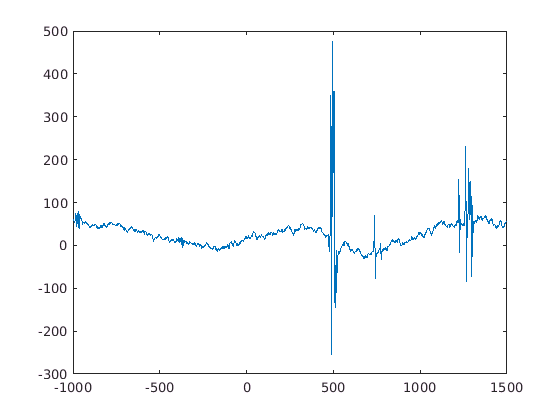

plot(emgtime, emg);

## Apply the filter

filtered = emg;
%for i=2:length(emg)-1
%    filtered(i) = emg(i)^2 - emg(i-1)*emg(i+1);
%end
%dont use loop!
filtered(2:end-1) = emg(2:end-1).^2 - emg(1:end-2).*emg(3:end);

## Plot the filtered signal

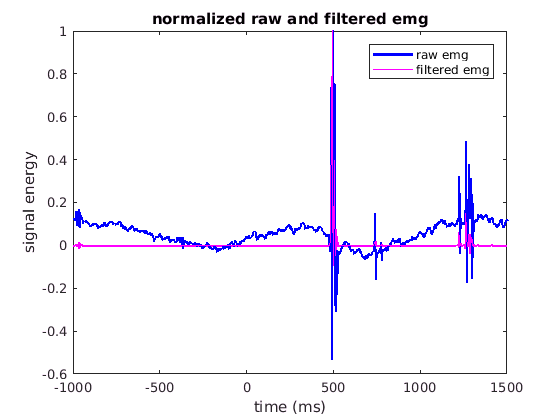

figure(1);
hold on;
emg_plot = plot(emgtime, emg./max(emg), 'b', 'linew', 2);
filtered_plot = plot(emgtime, filtered./max(filtered), 'm', 'linew', 1);
xlabel('time (ms)');
ylabel('signal energy');
title('normalized raw and filtered emg');
legend([emg_plot, filtered_plot], ["raw emg", "filtered emg"]);
hold off;

## Calculate the Z score

- (x - mu) / sigma

time0 = dsearchn(emgtime', 0); %find zero time
z_emg = (emg-mean(emg(1:time0))) / std(emg(1:time0));
z_filtered = (filtered-mean(filtered(1:time0))) / std(filtered(1:time0));

## Plot the z _scored signals

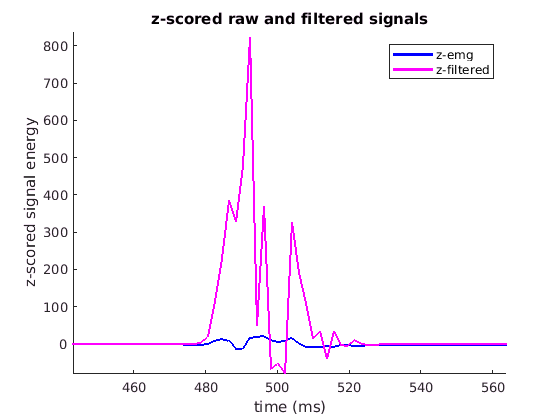

figure(2);
hold on;
emgz_plot = plot(emgtime, z_emg, 'b', 'linew', 2);
filteredz_plot = plot(emgtime, z_filtered, 'm', 'linew', 2);
xlabel('time (ms)');
ylabel('z-scored signal energy');
title('z-scored raw and filtered signals');
legend([emgz_plot, filteredz_plot], ["z-emg", "z-filtered"]);
%example region of interest
xlim([443 564])
ylim([-81 840])
hold off;